% Run params.m to retreive any parameters
params

% Load the simulink model 
sim('SingleMass.slx');
sim('MassSpring.slx');
sim('MassSpring_cancel_dynamics.slx');

set_param('SingleMass','SimMechanicsOpenEditorOnUpdate','off');
set_param('MassSpring','SimMechanicsOpenEditorOnUpdate','off');
set_param('MassSpring_cancel_dynamics','SimMechanicsOpenEditorOnUpdate','off');


testPoints = 50;
testOmega = zeros(testPoints, 1);
minOmega = 20; %1
maxOmega = 30; %25
multiplier = nthroot(maxOmega/minOmega, testPoints - 1);
for i = 1:testPoints
    testOmega(i) = minOmega * multiplier.^(i-1);
end

simTitle = 'MassSpring';
amplitude = 1;

set_param(strcat(simTitle, '/reference'),'Amplitude',string(amplitude));
energyArray     = zeros(length(testOmega), 1);
forceArray      = zeros(length(testOmega), 1);
refArray        = timeseries(length(testOmega), 1);
outputArray     = timeseries(length(testOmega), 1);

for i = 1:length(testOmega)
    set_param(strcat(simTitle, '/reference'),'Frequency',string(testOmega(i)));
    simOut = sim(simTitle,'ReturnWorkspaceOutputs','on');
    energyArray(i)  = simOut.energy.Data(end);
    forceArray(i)  = simOut.force.Data(end);
    refArray(i)     = simOut.ref;
    outputArray(i)  = simOut.pos;
end


kp = round(str2double(get_param(strcat(simTitle, '/plant input'),'P')));
kd = round(str2double(get_param(strcat(simTitle, '/plant input'),'D')));
ki = round(str2double(get_param(strcat(simTitle, '/plant input'),'I')));

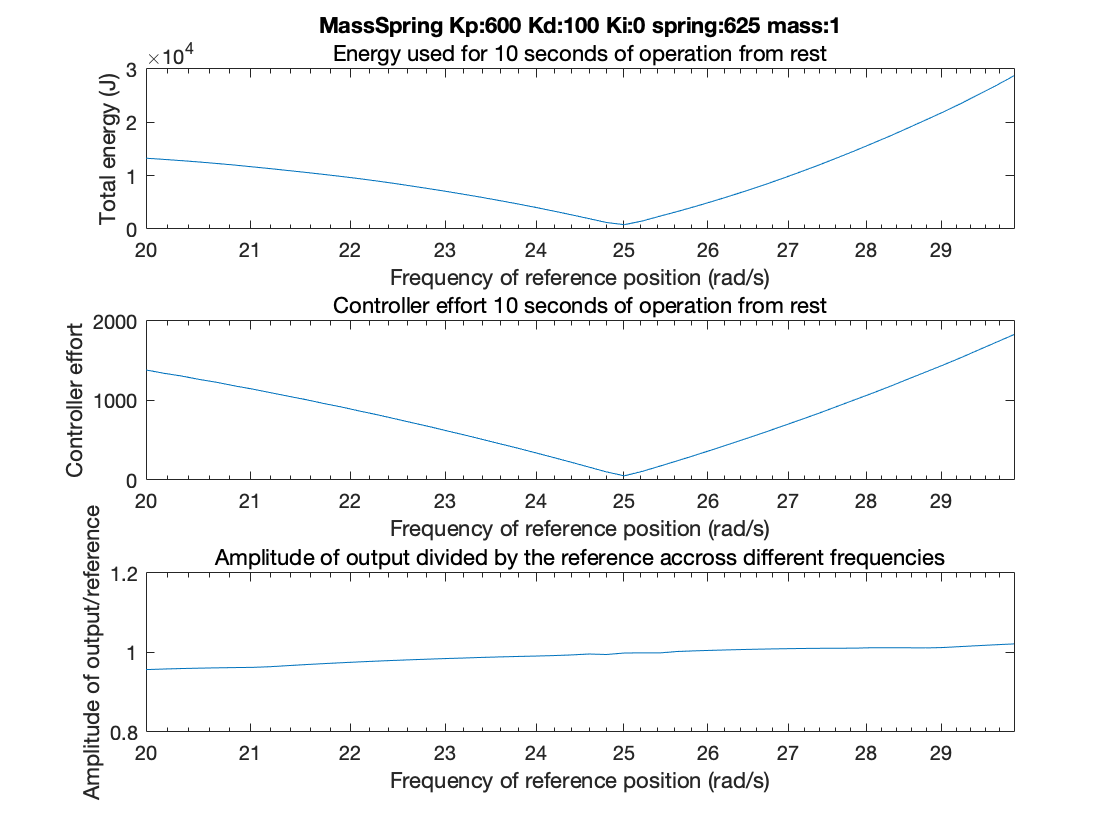


trackingArray   = zeros(length(testOmega), 1);
for i = 1:length(testOmega)
    trackingArray(i) = max(outputArray(i).Data(round(end/2):end))/amplitude;
end

subplot(3,1,1);
semilogx(testOmega, energyArray)
subtitle("Energy used for 10 seconds of operation from rest")
ylabel("Total energy (J)")
xlabel("Frequency of reference position (rad/s)")
title(strcat(simTitle, " Kp:", string(kp), " Kd:", string(kd), ...
    " Ki:", string(ki), " spring:", string(k), " mass:",string(m)));

subplot(3,1,2);
semilogx(testOmega, forceArray)
ylabel("Controller effort")
xlabel("Frequency of reference position (rad/s)")
subtitle("Controller effort 10 seconds of operation from rest");

subplot(3,1,3);
semilogx(testOmega, trackingArray)
hold on;
yline(amplitude *0.8);
yline(amplitude *1.2);
hold off;
ylabel("Amplitude of output/reference")
xlabel("Frequency of reference position (rad/s)")
subtitle("Amplitude of output divided by the reference accross different frequencies");

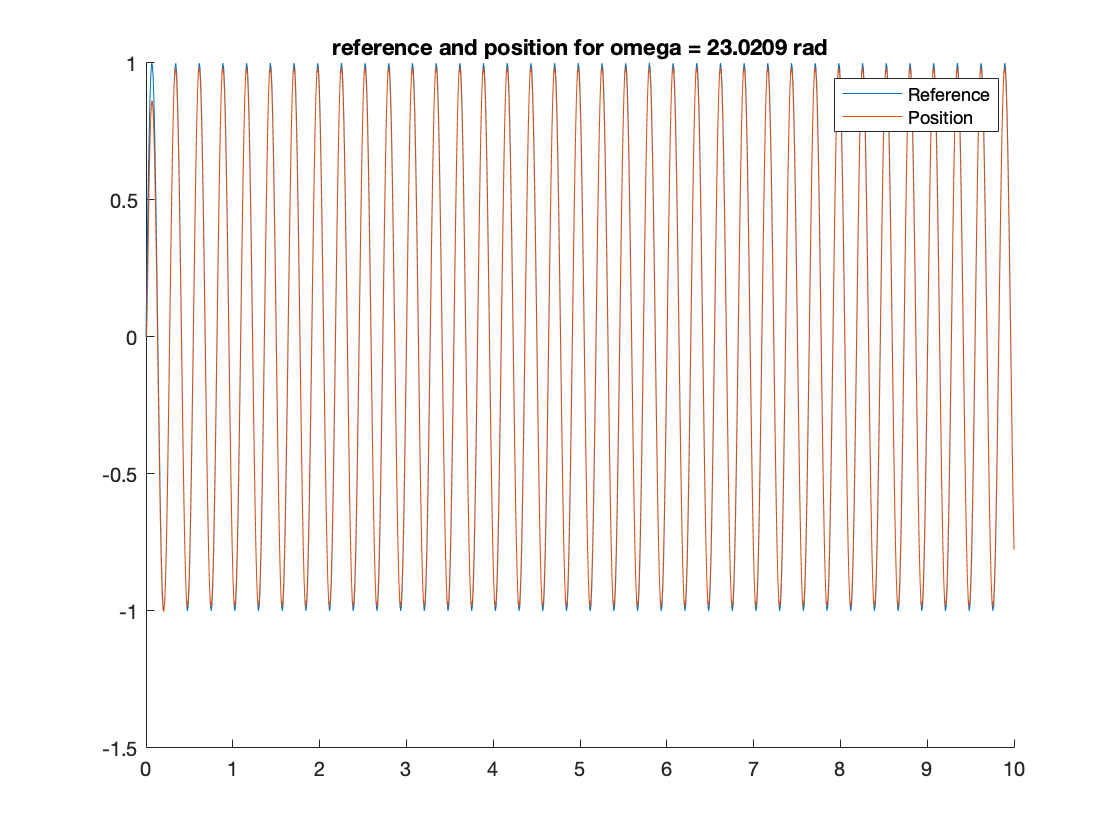

figure
hold on;
plot(refArray(18), "DisplayName", "Reference")
plot(outputArray(18), "DisplayName", "Position")
hold off;
legend;
title(strcat("reference and position for omega = ", string(testOmega(18)), " rad"));